Práctica 7

%parte del modelo de la planta siguiente:

A=[0 1; 0 -7.35]

A =          0    1.0000
         0   -7.3500


B=[0; 23.317]

B =          0
   23.3170


C=[4.91 0; 0 0.8179]

C =     4.9100         0
         0    0.8179


D=[0;0]

D =      0
     0


sys=ss(A,B,C,D);
G=tf(sys)

G =
 
  From input to output...
          114.5
   1:  ------------
       s^2 + 7.35 s
 
        19.07
   2:  --------
       s + 7.35
 
Continuous-time transfer function.



C*B

ans =          0
   19.0710


C*A*B

ans =   114.4865
 -140.1717


rank([0 0 114.48; 0 19.071 -140.1717])

ans = 2

% es controlable de salida.

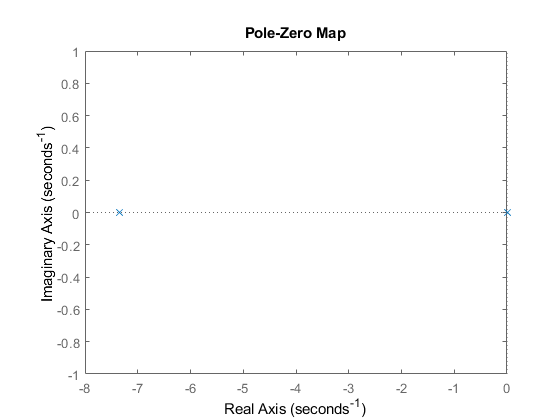

pzmap(G)

rank(ctrb(A,B))

ans = 2

%el polo en bucle abierto esta cerca de -6.25
%el polo deseado estara cerca de este valor

Obtención del vector de ganancias de realimentación

T=0.001;
 e=0.51;
 wn=14.2;
Pb2=[1 2*e*wn wn^2];
Ps2=roots(Pb2)

Ps2 =   -7.2420 +12.2145i
  -7.2420 -12.2145i


Pz2=exp(Ps2*T)

Pz2 =    0.9927 + 0.0121i
   0.9927 - 0.0121i


sysd=c2d(sys,T,'zoh')

sysd =
 
  A = 
              x1         x2
   x1          1  0.0009963
   x2          0     0.9927
 
  B = 
              u1
   x1  1.163e-05
   x2    0.02323
 
  C = 
           x1      x2
   y1    4.91       0
   y2       0  0.8179
 
  D = 
       u1
   y1   0
   y2   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.



Co=ctrb(sysd.A,sysd.B)

Co =     0.0000    0.0000
    0.0232    0.0231


rank(Co)

ans = 2

det(Co)

ans = -5.3970e-07

V=obsv(sysd.A,sysd.C)

V =     4.9100         0
         0    0.8179
    4.9100    0.0049
         0    0.8119


rank(V)

ans = 2




H=acker(sysd.A,sysd.B,Pz2)

H =     8.6169    0.3081



%observador reducido

Abb=sysd.A(2,2);
Aab=sysd.A(1,2);
Lr=acker(Abb,Aab,0.9523)

Lr = 40.5255


%estimador eatado actual
% AC=(sysd.C)'*(sysd.A)'
% At=(sysd.A)'
% Lest=acker(At,AC,Pz2)

Control integral mediante variables de integración

% % En caso de añadir una nueva variable de estados porque solo considero uno de las dos salidas del sistema 

%1

Aa=[sysd.A(1,1) sysd.A(1,2) 0; sysd.A(2,1) sysd.A(2,2) 0; -sysd.C(1,1) -sysd.C(1,2) 1]

Aa =     1.0000    0.0010         0
         0    0.9927         0
   -4.9100         0    1.0000


Ba=[sysd.B(1,1);sysd.B(2,1);0];

%2
Pba=conv(Pb2,[1 8]) %  añado el polo que me piden

Pba = 	1.0e+03 *

    0.0010    0.0225    0.3175    1.6131


Ps=roots(Pba)

Ps =   -7.2420 +12.2145i
  -7.2420 -12.2145i
  -8.0000 + 0.0000i


Pz=exp(Ps*T)

Pz =    0.9927 + 0.0121i
   0.9927 - 0.0121i
   0.9920 + 0.0000i



%3
Ha=acker(Aa,Ba,Pz)

Ha =    13.5832    0.6486   -0.0140



% anti wind up. limito la X3

%X3=(1/Ha(3))*()--- seguir pensando-.


%prueba
% Ca=[0.2022 0 0; 0 1.22 0;0 0 0]
% D=0
% sysp=ss(Aa,Ba,Ca,D);
% Gp=tf(sys)
% Hp=[Ha(1,1) Ha(1,2) Ha(1,3); 0 0 0]
% step(feedback(sysp,Hp,-1))


% En caso de añadir dos nuevas variables estados porque le sistema tiene
%dos salidas.

% %1
% Aa=[sysd.A(1,1) sysd.A(1,2) 0 0; sysd.A(2,1) sysd.A(2,2) 0 0; -sysd.C(1,1) -sysd.C(1,2) 1 0;-sysd.C(2,1) -sysd.C(2,2) 0 1]
% Ba=[sysd.B(1,1);sysd.B(2,1);0;0];
% Ca=[sysd.C(1,1) sysd.C(1,2) 0 0;sysd.C(2,1) sysd.C(2,2) 0 0];
% 
% 
% %2
% Pba=conv(Pb,[70 73.125 ]) %  añado el polo que me piden
% Pbaa=conv(Pba,[1 96]) %añado otro polo muy alejado para conseguir obtener H
% Psa=roots(Pbaa)
% Pza=exp(Psa*T)
% 
% %3-- > he tenido que añadir un polo en cero para conseguir que Pza tenga la
% %misma dimension que Aa.
% Ha=acker(Aa,Ba,Pza)

### práctica 7. cogiendo un polinomio que considero mas adecuado  ya que me da una H ma pequeña.

% intoento colocar los polos deseados lo mas cercano posible a los polos de
% buble abierto y obteniendo un tiempo de establecimiento no muy grande.
% los coloco en -9. obtengo un tiempo de establecimiento entorno a 0.5, 
T=0.001;
 ep=0.51;
 wn=14.2;
 Pd=[1 2*ep*wn wn^2];
%Pd=[1 20.945 527.566]
Ps=roots(Pd)

Ps =   -7.2420 +12.2145i
  -7.2420 -12.2145i


Pz=exp(Ps*T)

Pz =    0.9927 + 0.0121i
   0.9927 - 0.0121i


sysd=c2d(sys,T,'zoh');

H=acker(sysd.A,sysd.B,Pz)

H =     8.6169    0.3081



%1

Aa=[sysd.A(1,1) sysd.A(1,2) 0; sysd.A(2,1) sysd.A(2,2) 0; -sysd.C(1,1) -sysd.C(1,2) 1]

Aa =     1.0000    0.0010         0
         0    0.9927         0
   -4.9100         0    1.0000


Ba=[sysd.B(1,1);sysd.B(2,1);0];

% el nuevo sisteema amplidado que puedo servir de observador tambien 

Ca=[sysd.C(1,1) sysd.C(1,2) 0;sysd.C(2,1) sysd.C(2,2) 0; 0 0 0];
Da=[0;0;0];
sysa=ss(Aa,Ba,Ca,Da)

sysa =
 
  A = 
              x1         x2         x3
   x1          1  0.0009963          0
   x2          0     0.9927          0
   x3      -4.91          0          1
 
  B = 
              u1
   x1  1.163e-05
   x2    0.02323
   x3          0
 
  C = 
           x1      x2      x3
   y1    4.91       0       0
   y2       0  0.8179       0
   y3       0       0       0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



aa=Aa';
cc=Ca';


%2
Pba=conv(Pd,[1 10.86]) %  añado el polo que me piden

Pba = 	1.0e+03 *

    0.0010    0.0253    0.3589    2.1898


Ps=roots(Pba)

Ps =   -7.2420 +12.2145i
  -7.2420 -12.2145i
 -10.8600 + 0.0000i


Pz=exp(Ps*T)

Pz =    0.9927 + 0.0121i
   0.9927 - 0.0121i
   0.9892 + 0.0000i



%3
Ha=acker(Aa,Ba,Pz)

Ha =    15.3490    0.7696   -0.0190


% L=acker(aa,cc,Pz)
% no se si es necesario calculllar la r para obte

% diseño del pid

G1=tf([128.4],[1 9.091 0])

G1 =
 
      128.4
  -------------
  s^2 + 9.091 s
 
Continuous-time transfer function.



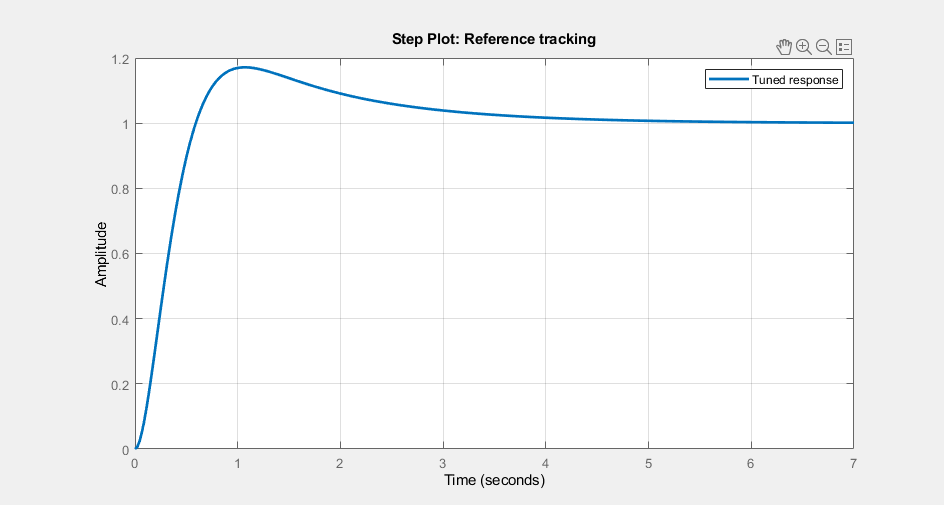

pidtool(G1)

  Kp + Ki * 1/s

  with Kp = 0.674, Ki = 0.08